# Frequency Response & Polar Diagrams

## Introduction - Polar Diagrams of the Frequency Response

Consider an **asymptotically stable** LTI continuous-time that is **fully described** (that is, no common factors, i.e. no hidden dynamics) by the transfer function $G(s)$

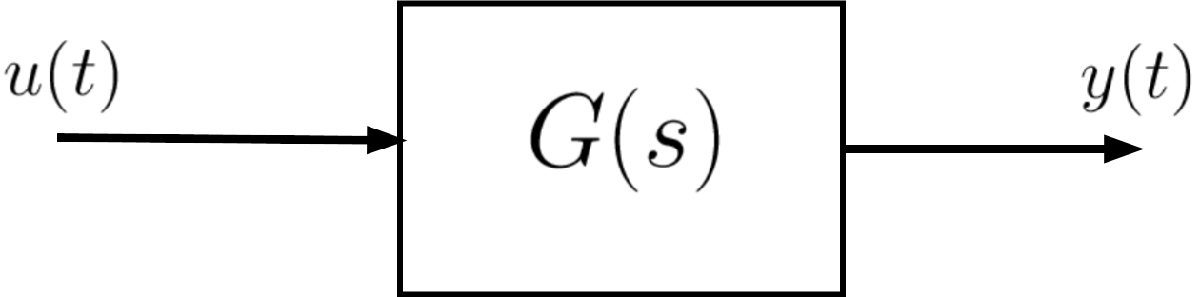

Moreover, consider $u(t) = \big[A \sin \big(\bar{\omega}\,t\big) \big]\cdot 1(t)\quad \Longrightarrow \quad \mathcal{L}\left(u(t)\right) = U(s) = \frac{A\,\bar{\omega}}{s^2+\bar{\omega}^2}$

The regime sinusoidal response (approx. equal to $y(t)$ for $t> t_s$, where $t_s$ is the settling time of the step response of the system $G(s)$) is:


$$y_{\text{reg.}}(t) = \Big[\big\vert G\left(j\,\bar{\omega}\right) \big\vert \cdot A \,\sin \big(\bar{\omega}\,t+\bar{\varphi}\big) \Big]\,1(t)\,,\quad \bar{\varphi} = \text{arg}\, G\big(j\,\bar{\omega}\big)$$


The **frequency** **response** of the system is defined as: $G\big(j\,\omega\big)\,,\quad \omega \ge 0$

Polar and Bode diagrams are related:


$$G\big(j\,\omega\big) = \left| G\left(j\,\omega\right)\right\vert\,e^{j\,\arg G(j\,\omega)}
= \text{Re}\big[ G\left(j\,\omega\right)\big] + j\,\text{Im}\big[G\left(j\,\omega\right)\big]
$$


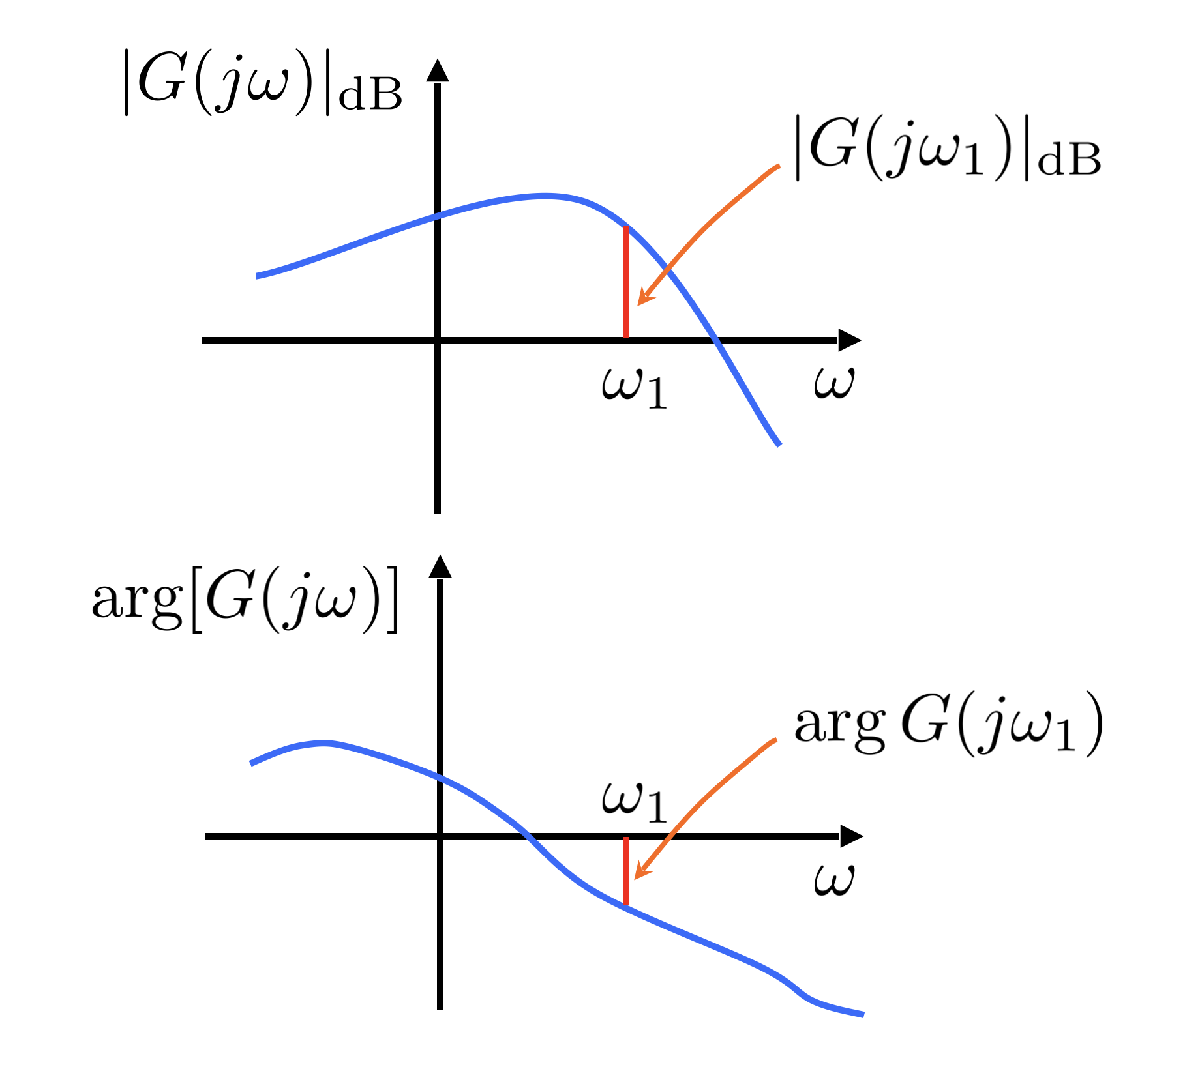  $\qquad \Longleftrightarrow \qquad$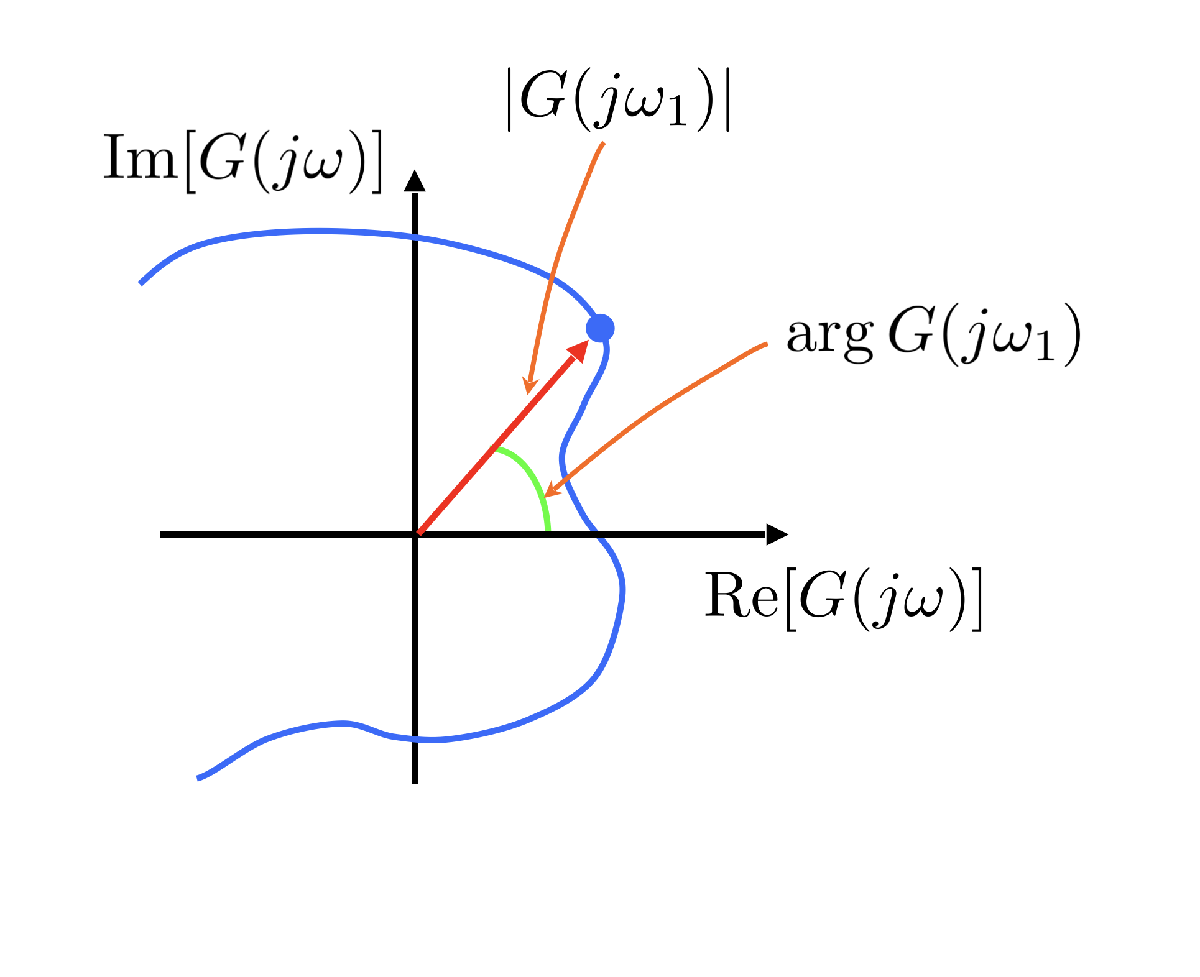


$$\begin{array}{ccccc}
\text{Bode diagrams} & \qquad \qquad &\qquad \qquad &\qquad \qquad& \text{Polar diagram}
\end{array}$$


## With a Little Help from the 'help' Command!

Here is the documentation related to the Control System Toolbox function we will use in this live script:

help evalfr

--- help for DynamicSystem/evalfr ---

 DynamicSystem/evalfr - Evaluate system response at specific frequency
    evalfr is a simplified version of freqresp meant for quick evaluation of
    the system response at any point in the complex plane.

    Syntax
      frsp = evalfr(sys,x)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      x - Point in complex plane
        complex scalar

    Output Arguments
      frsp - Frequency response
        complex scalar | complex array

   


help freqresp

 freqresp - Evaluate system response over a grid of frequencies
    Use freqresp to evaluate the system response over a grid of frequencies.

    Syntax
      [H,wout] = freqresp(sys)
      H = freqresp(sys,w)
      H = freqresp(sys,w,units)
      [H,wout,covH] = freqresp(sys,___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      w - Frequencies
        vector
      units - Units of the values in the input frequency vector
        rad/Tim


help nyquist

 nyquist - Nyquist response of dynamic system
    This MATLAB function returns the real and imaginary parts of the
    frequency response at each frequency in the vector wout.

    Syntax
      [re,im,wout] = nyquist(sys)
      [re,im,wout] = nyquist(sys,w)
      [re,im,wout,sdre,sdim] = nyquist(sys,w)

      nyquist(___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      w - Frequencies
        {wmin,wmax} | vector | []

    Output Arguments
      


help bode

 bode - Bode frequency response of dynamic system
    This MATLAB function computes the frequency response of dynamic system
    model sys and returns the magnitude and phase of the response at each
    frequency in the vector wout.

    Syntax
      [mag,phase,wout] = bode(sys)
      [mag,phase,wout] = bode(sys,w)
      [mag,phase,wout,sdmag,sdphase] = bode(sys,w)

      bode(___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      w - Frequencies
        {wmin,wmax} | vector | []

    Output Arguments
      

Moreover, the following custom functions are available:

addpath(genpath("BodeDiagram"))

help asympt_bode

  *** asympt_bode(SISOmodel, om_vector) ***
  [MagData,PhaseData,out_om_v] = asympt_bode(SISOmodel, om_vector)
 
  Asymptotic Bode diagram of a transfer function.%
  The SISOmodel can be any of the available LTI system models, 
  i.e. a tf object (preferred), an ss object or a zpk object.  
  In the event that SISOmodel is not a tf object, it is converted to tf.
 
  om_vector -->  angular frequency values used to draw the graphs 
                (OPTIONAL - if not present, a suitable frequency range 
                 is estimated on the basis of zeros and poles. An 
                 appropriate number of values for the angular pulsation 
                 in the newly determined range is then chosen).
 
  If MagData and PhaseData vectors are not requested in the output,
  asymptotic modulus and phase graphs are plotted in graphs 
  on a semi-logarithmic scale.
  The array out_om_v contains the angular frequency values 
  used to compute the asymptotic d


help drawBodediagrams

   drawBodediagrams( )
   Plotting Bode diagrams of the frequency response 
  (asymptotic and actual superimposed diagrams) of 
  continuous-time transfer functions. 
 
  INPUT variables:
  Gs: transfer function, described as TF object; MANDATORY variable
 
  omega_values: angular frequency values used to draw the graphs 
                (OPTIONAL - if not present, a suitable frequency range 
                 is estimated on the basis of zeros and poles. An 
                 appropriate number of values for the angular pulsation 
                 in the newly determined range is then chosen).
 
  asBode_color: colour of asymptotic graphs 
                (array: three values between 0 and 1) - OPTIONAL
                Default value: [1, 0, 0] <--> red
 
  asBode_line_width: line thickness for asymptotic graphs - OPTIONAL
                Default value: 2 
 
  asBode_line_style: line style for asymptotic diagrams 
                     (see 'LineStyle' in plot( ) ) - OPTI


help drawPolarDiagramFreqResp

   drawPolarDiagramFreqResp( )
   Plotting polar diagrams of the frequency response 
   of continuous-time transfer functions. 
 
  INPUT variables:
  Gs: transfer function, described as TF object; MANDATORY variable
 
  omega_values: angular frequency values used to draw the graphs 
                (OPTIONAL - if not present, a suitable frequency range 
                 is estimated).
  
  polar_color: colour of actual graphs 
              (array: three values between 0 and 1) - OPTIONAL
                Default value: [0, 0, 1] <--> blue
 
  polar_line_width: line thickness for actual graphs - OPTIONAL
                Default value: 2.0
 
  polar_line_style: line style for actual diagrams 
                   (see 'LineStyle' in plot( ) ) - OPTIONAL
                   Default value: '-' 
 
  markerSize: is the size (in pt.) of the circular markers used 
              to put in evidence the points in the polar draw 
              corresponding to null angular frequency

### Remark

Please, refer to the live script named [LTIfreqRespBODEDiagrams.mlx](matlab:open('./LTIfreqRespBODEDiagrams.mlx')) for examples on how to use `evalfr( )`, `freqresp( )`, `bode( )`, `asympt_bode( )` and `drawBodediagrams( )`.

## Polar Diagrams of the Frequency Response using MATLAB

### Example 1: A Strictly Proper Transfer Function with Real Poles 

Consider the LTI  system described by the transfer function:


$$G(s) = \frac{10}{\left(1+10\,s\right)\,\left(1+2\,s\right)}\;,\qquad 
\left\{\begin{array}{ll}
g=0 & \mu = 10 \\
\tau_1 = 10 & \tau_2 = 2\\
\omega_1 = 0.1 & \omega_2 = 0.5
\end{array} \right.$$


The polar diagram of the frequency response of $G(s)$ is

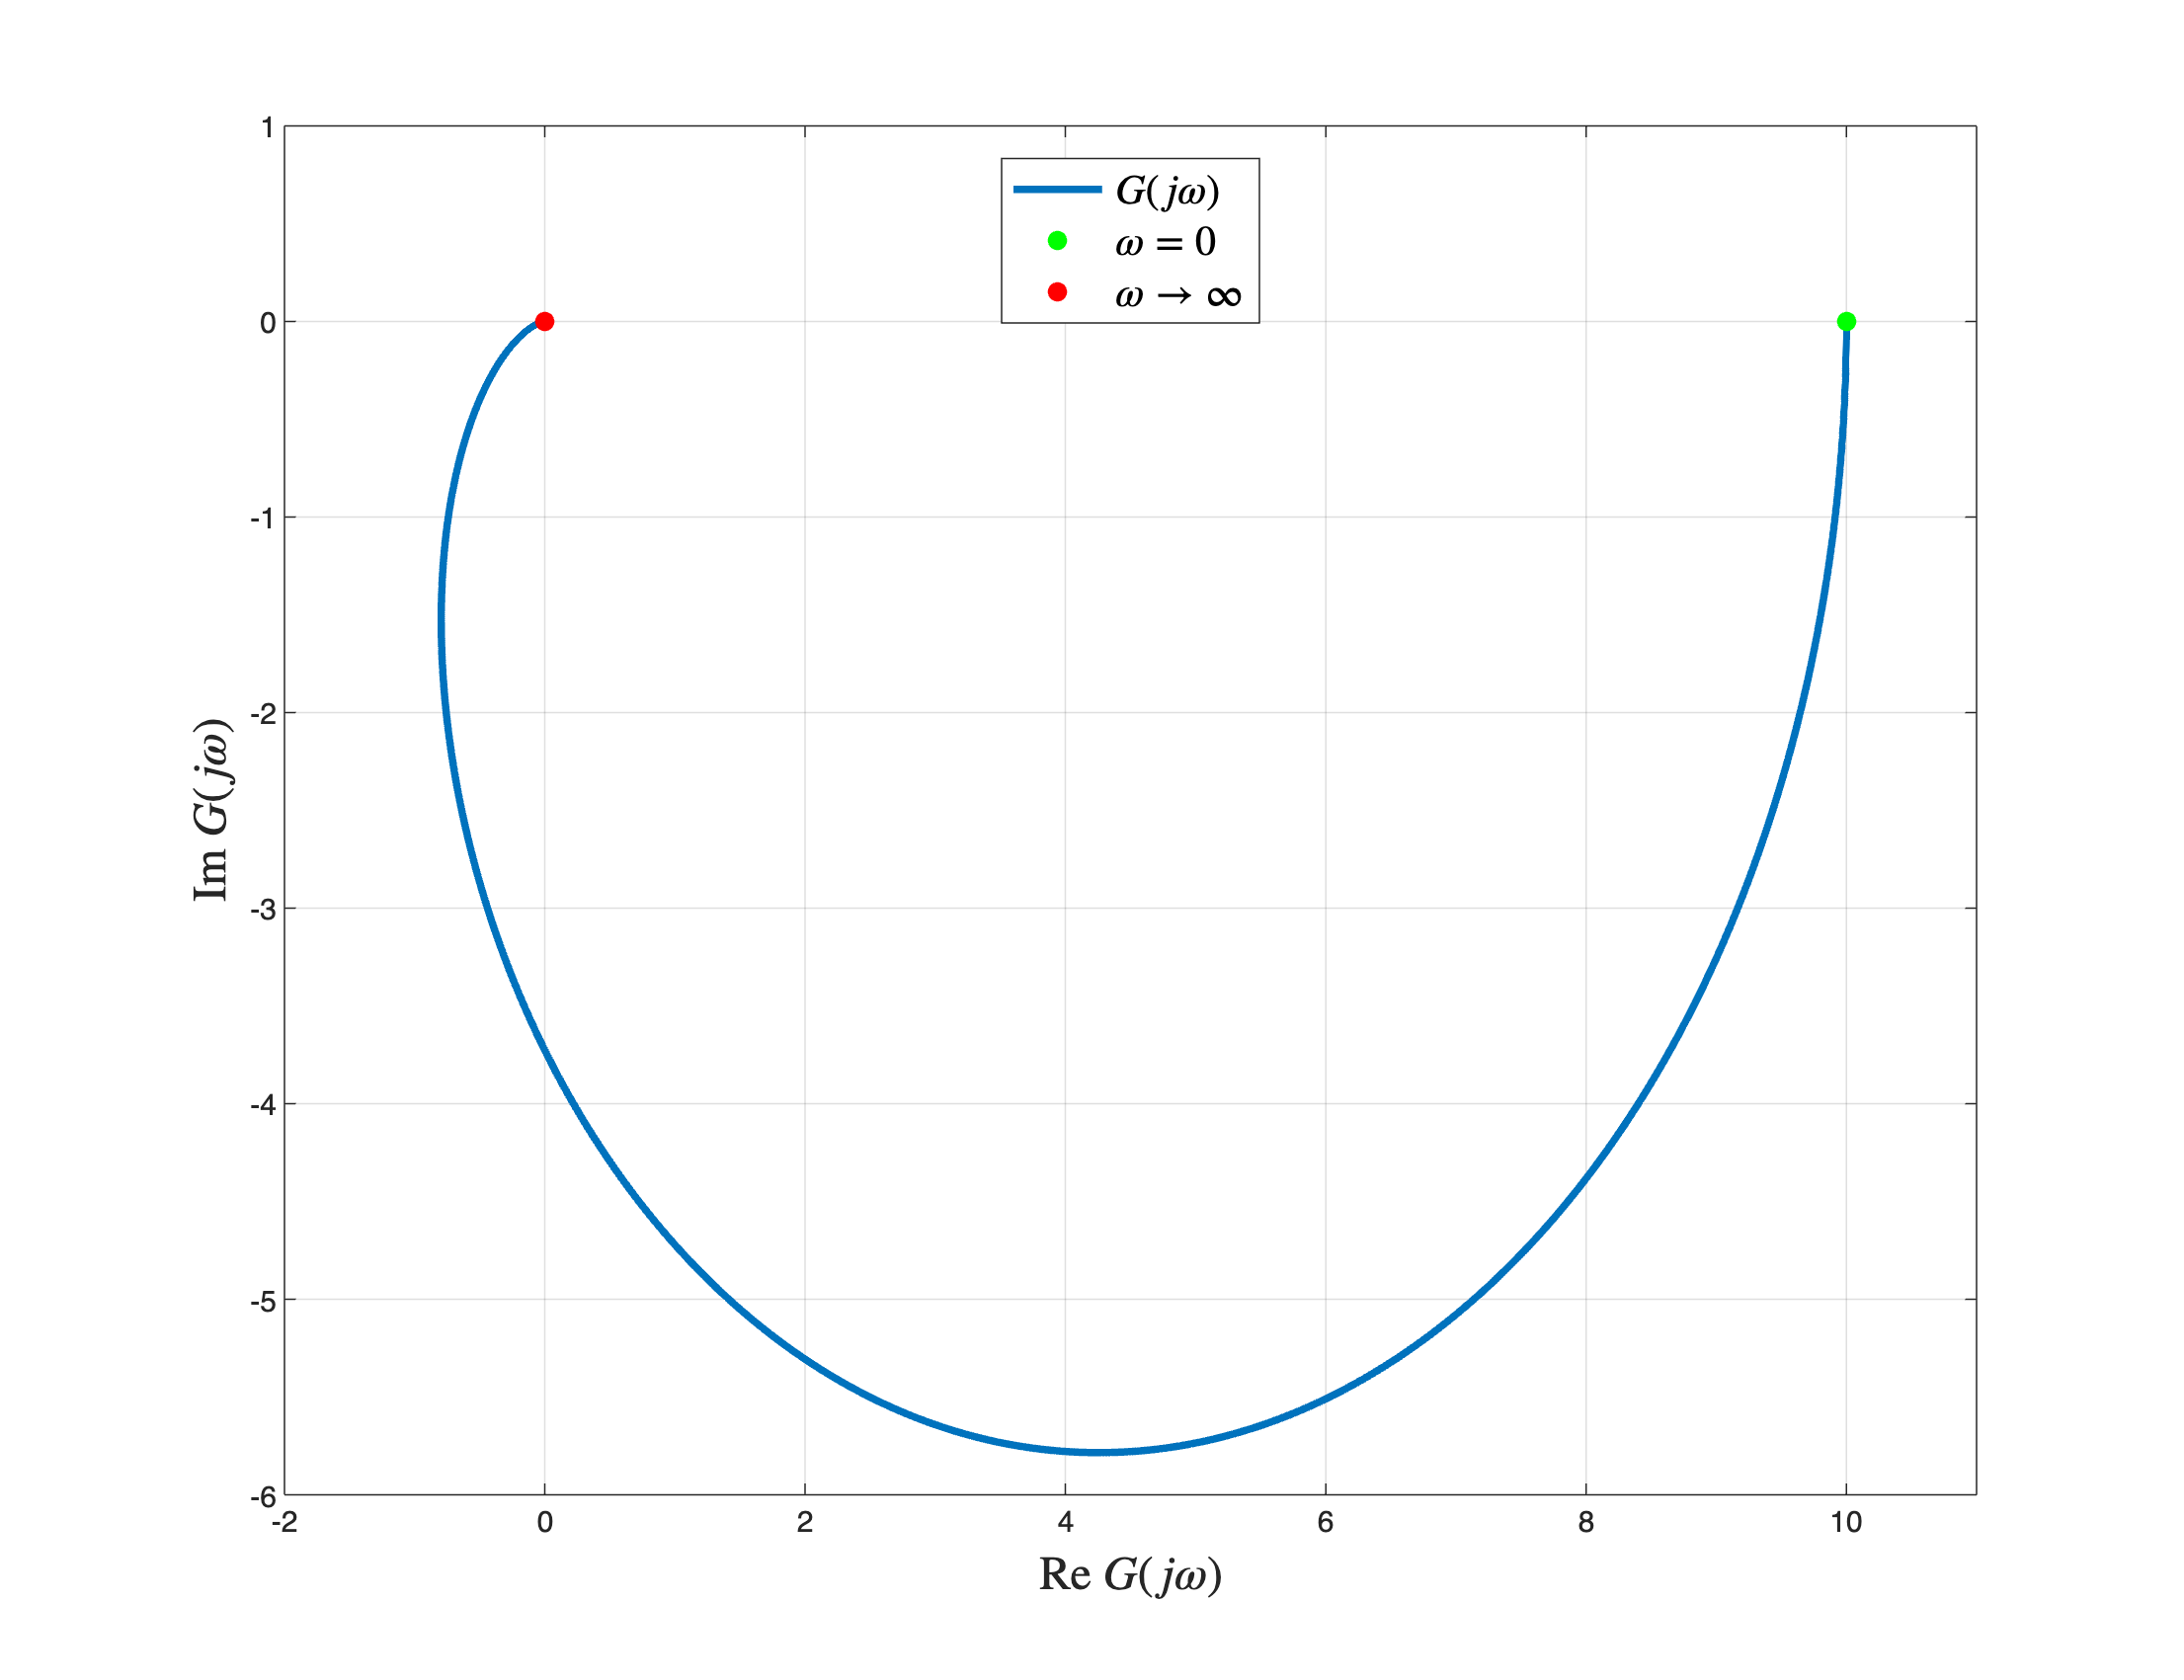

clear
s=tf('s');

Gs = 10/((1+10*s)*(1+2*s));

omVALS = logspace(-10,6, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-10 and 10^6 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the diagram.

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 26, 20]);
drawPolarDiagramFreqResp(Gs, omVALS, Bcolors(1, :), 2.5, '-', 6, [], hf, true);

### Example 2: A Couple of Complex Poles, varying the Damping Factor

Consider the LTI  system described by the transfer function:


$$G(s) = \frac{25}{25+10\,\xi\,s + s^2}\;,\qquad \xi = 0.9,\, 0.7,\,0.5,\,0.3,\,0.1 \quad \omega_n = 5\;\text{rad/s}$$


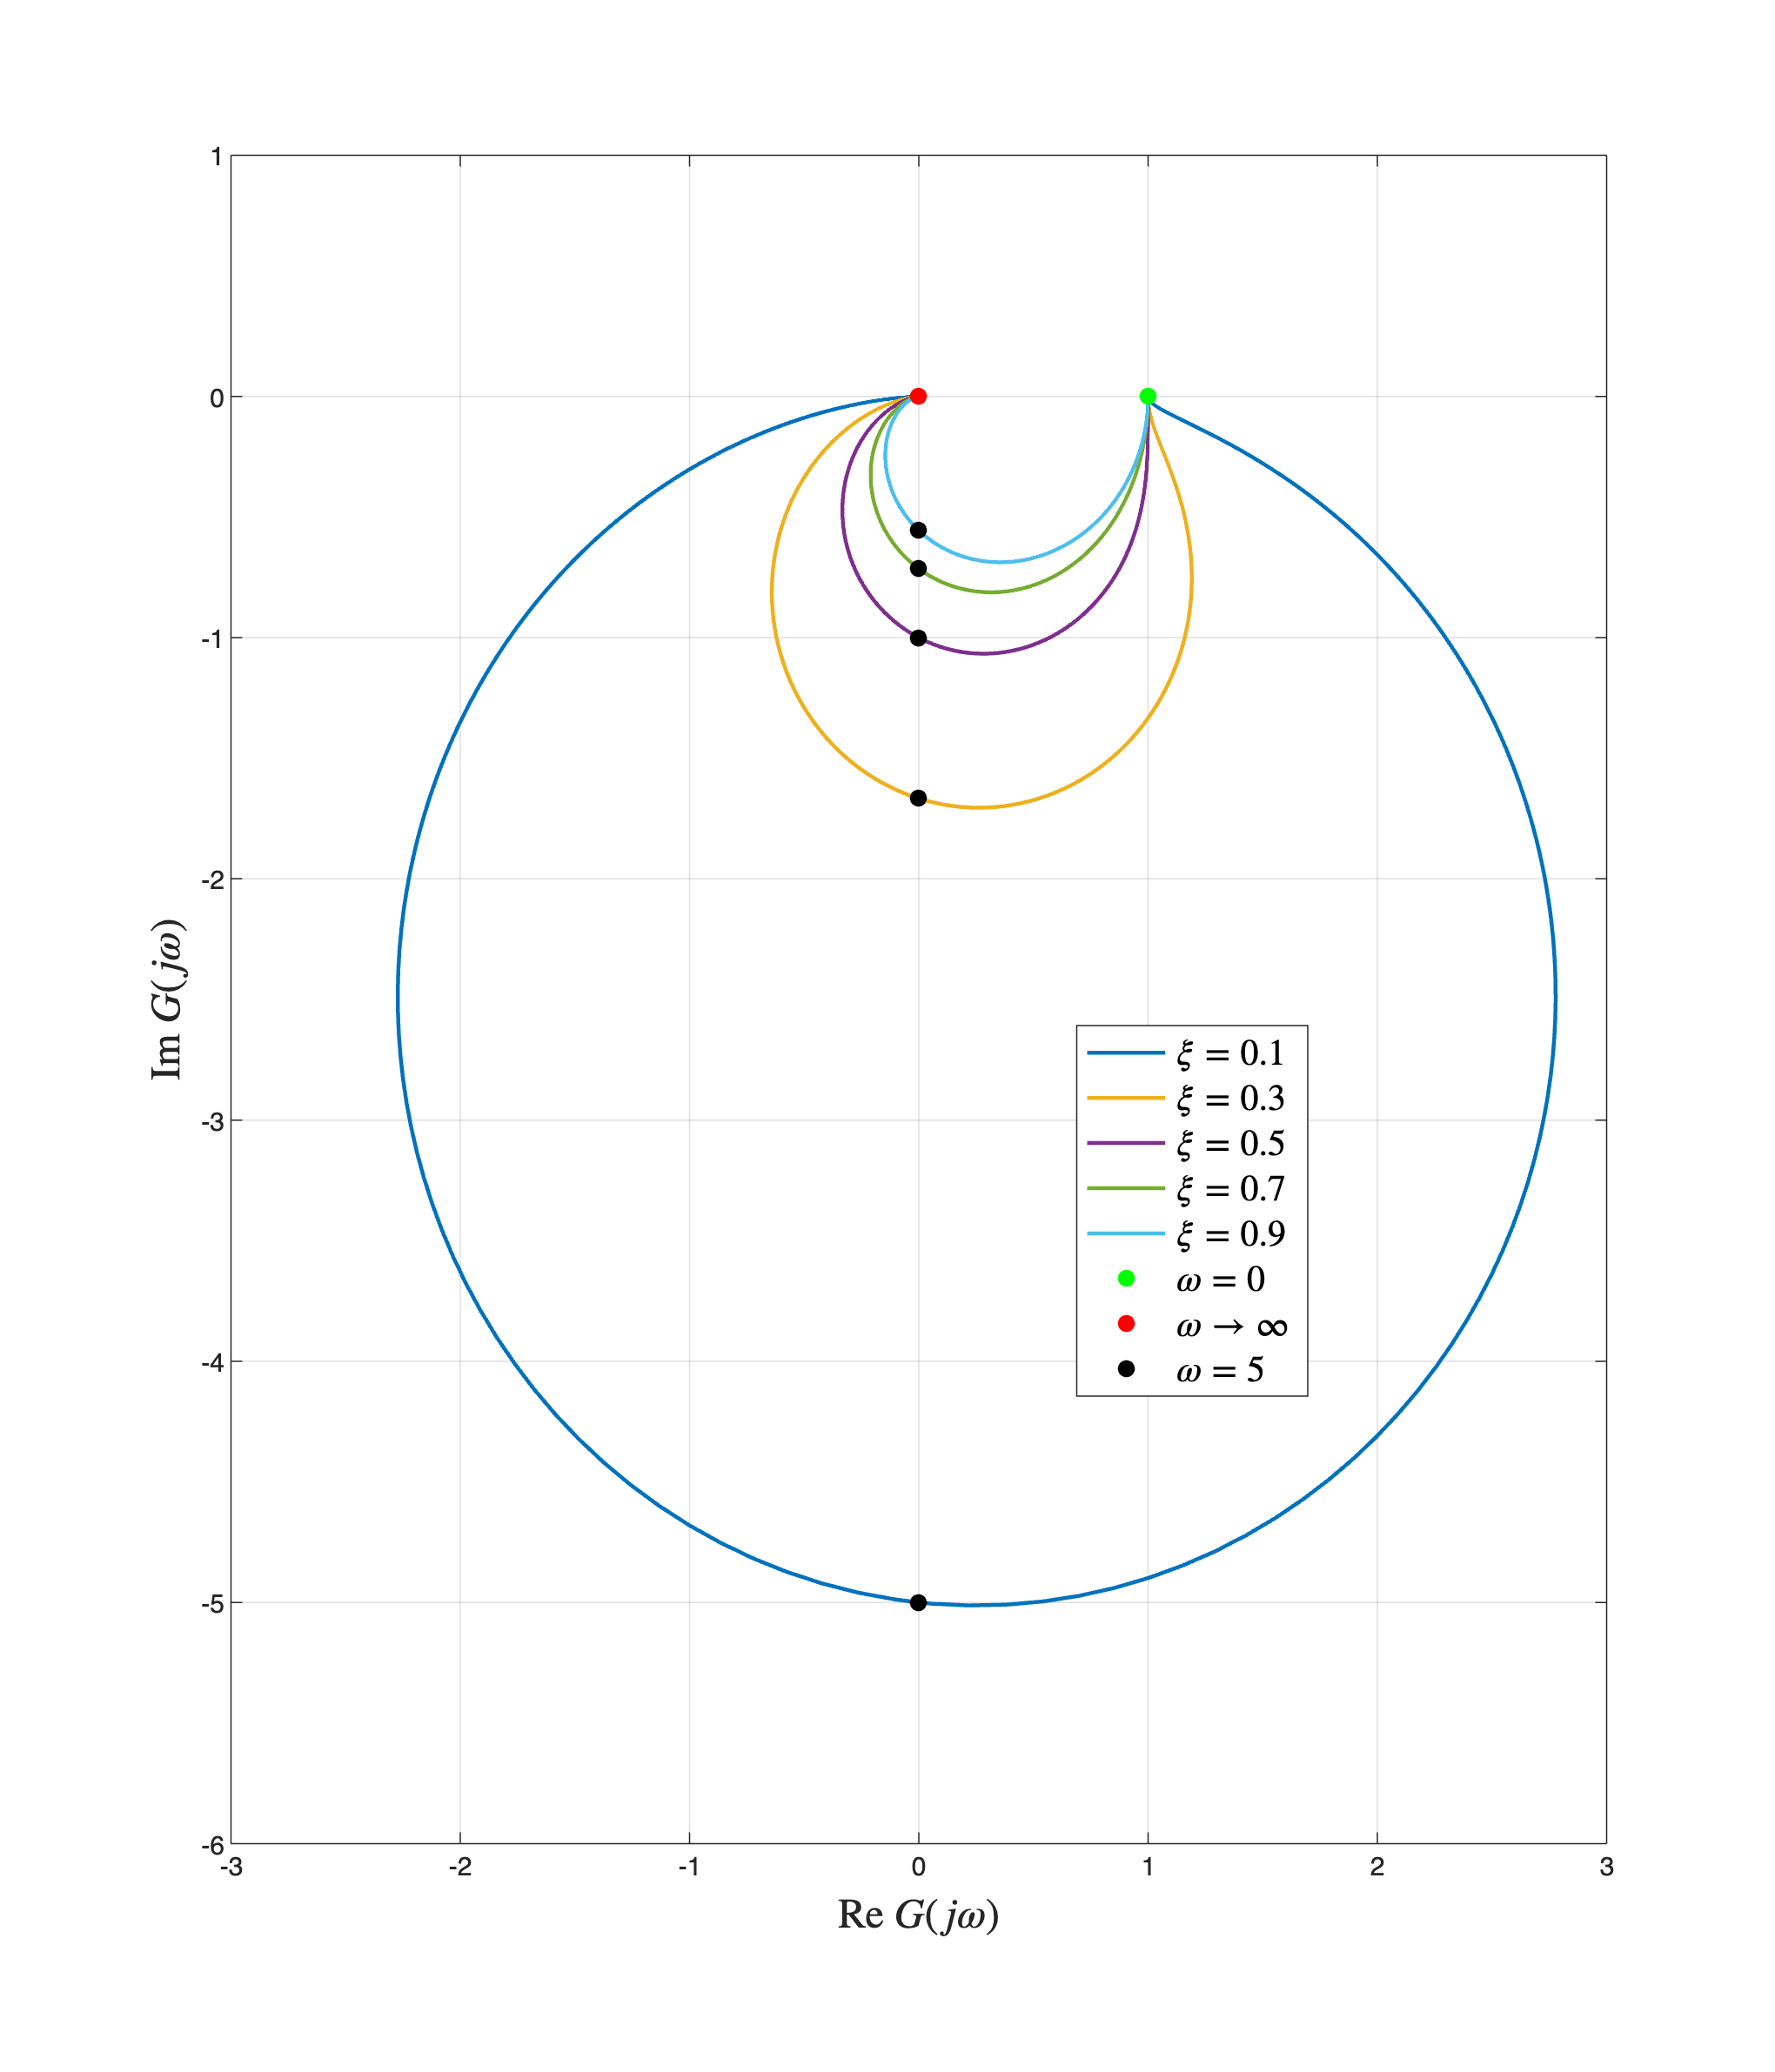

clear

xiVAL = [0.1, 0.3, 0.5, 0.7, 0.9]; % the damping factor values
Nxi = numel(xiVAL); % how many damping factors?

Gs_xi = cell(Nxi, 1); 
% let's preallocate a data-structure for storing the different transfer functions

% generate the transfer functions, with different damping factors
numGs = 25; % the coeffs of the polynomial at the numerator in G(s)
for n=1:Nxi
    denGs = [ (1)  (10*xiVAL(n))   25];
    % the coeffs of the polynomial at the denominator in G(s), 
    % in descending order
    Gs_xi{n} = tf(numGs, denGs); % let's define the transfer function G(s)
                                 % and store it in the data-structure
end % for

omVALS = logspace(-10,4, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-10 and 10^4 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the plot.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawPolarDiagramFreqResp( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
%t = tiledlayout(2, 3); % let's create rooms for plots in a 3x3 grid
%nextile(1); % % let's move to tile 1
for n=1:Nxi
    hax = drawPolarDiagramFreqResp(Gs_xi{n}, omVALS, ...
                       Bcolors(n, :), 1.5, '-', 6, 5, hf, false);
end % for
legend(hax, ['$\xi = ',num2str(xiVAL(1)),'$'], '', '', '',...
             ['$\xi = ',num2str(xiVAL(2)),'$'], '', '', '',...
             ['$\xi = ',num2str(xiVAL(3)),'$'], '', '', '',...
             ['$\xi = ',num2str(xiVAL(4)),'$'], '', '', '',...
             ['$\xi = ',num2str(xiVAL(5)),'$'], '$\omega =0$', '$\omega \to \infty$' ,...
             '$\omega =5$', 'Interpreter','latex', 'fontsize',14, 'Location', 'best');

### Example 3: a Minimum-Phase LTI System with a Pole at the Origin

Consider the LTI  system described by the transfer function:


$$G(s) = \frac{s+10}{s\left(s+1\right)} = 10\,\frac{\left(1+\frac{s}{10}\right)}{s\left(1+s\right)}$$


Analysing the transfer function, you get


$$\left\{ \begin{array}{rcl}
g & = &1 \\
\mu & = & 10 \; \Longrightarrow \; \mu_{\text{dB}} = 20\,\text{dB}
\end{array} \right. \qquad
\left\{ \begin{array}{rcl}
z_1 &=& -10\\
p_1 &=& 0 \\
p_2 &=& -1\\
\end{array} \right.$$


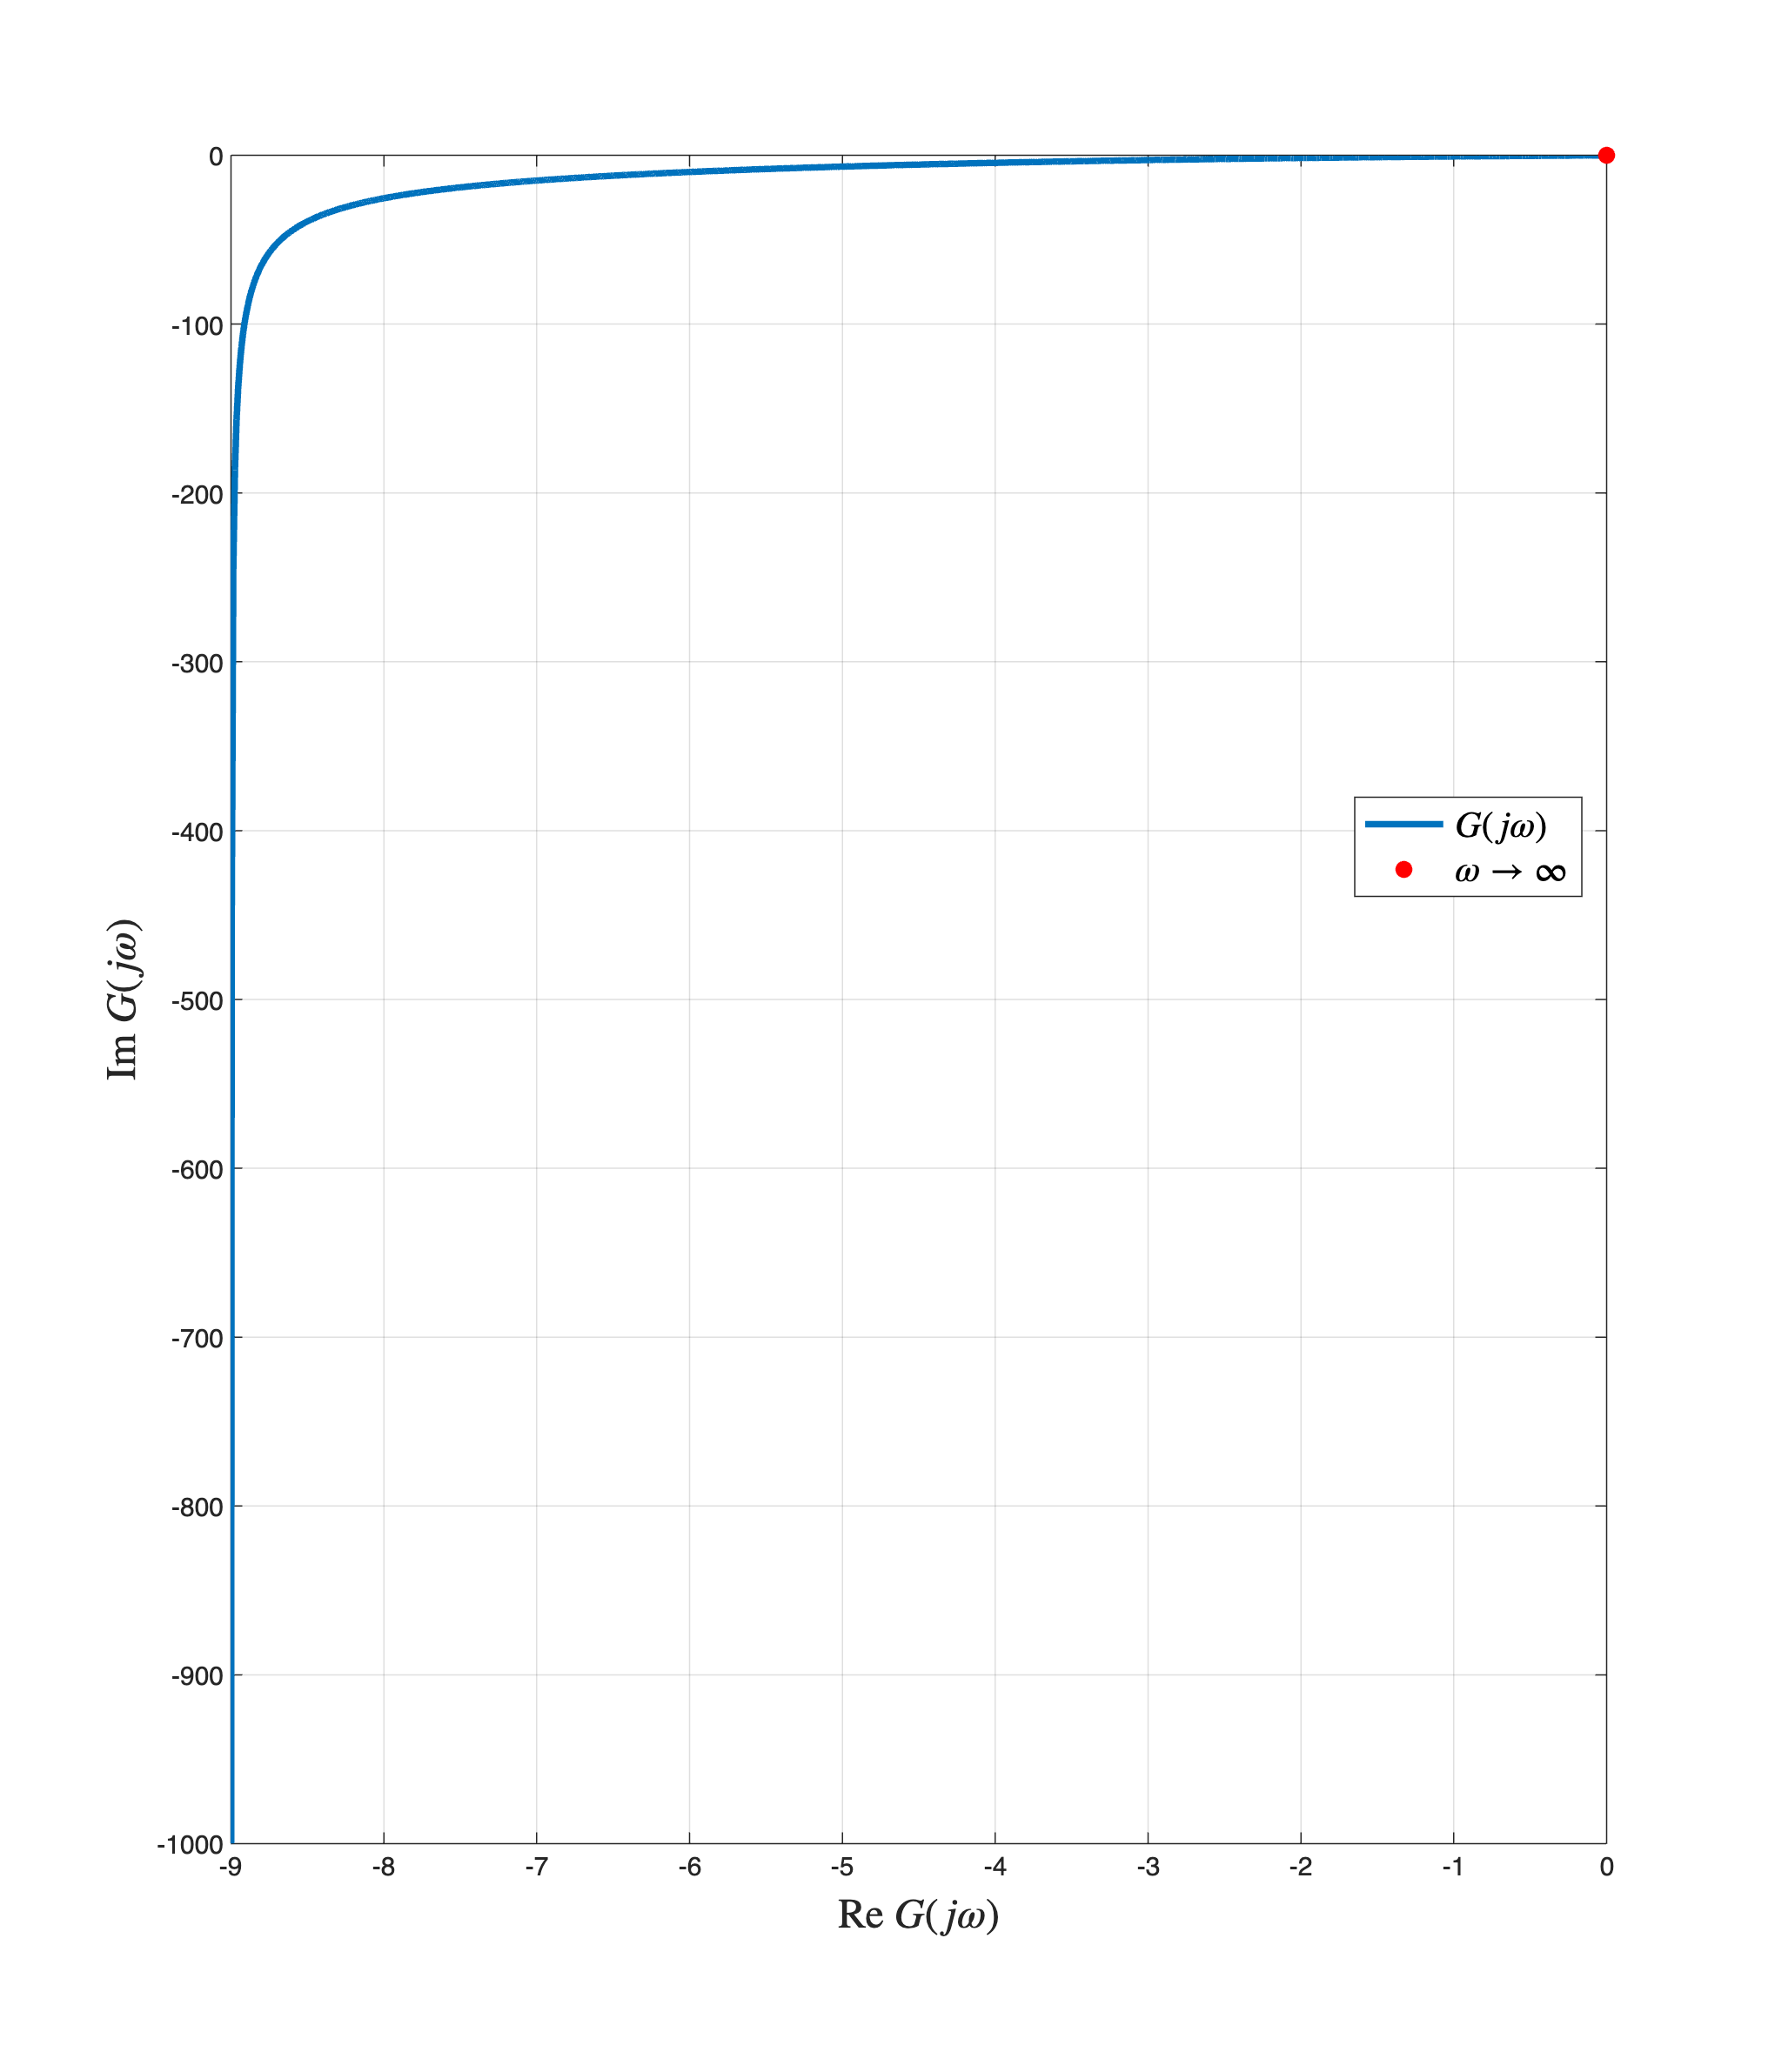

clear
s = tf('s'); % the transfer function building helper

Gs = (s+10)/(s * (1+s) );


omVALS = logspace(-2,3, 5e4); % <-- Modify this interval and see what the plot looks like.

% We want to evaluate the frequency response at 50000 
% angular pulsation values between 10^-2 and 10^3 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the diagram.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawPolarDiagramFreqResp( )

Bcolor = [0 0.4470 0.7410]; % a different color for the actual diagram

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

 hax = drawPolarDiagramFreqResp(Gs, omVALS, ...
                       Bcolor, 2.5, '-', 6, [], hf, false);
legend(hax, '$G(j \omega)$', '', '$\omega \to \infty$' ,...
             'Interpreter','latex', 'fontsize',14, 'Location', 'best');


rmpath(genpath("BodeDiagram"))